# Seminararbeit: Visualisierung der Daten

## Adam Müller 202383 | WS 21/22

Dieser Code erhält die Daten der kapazitiven-, sowie der Temperatur-Messung und stellt diese graphisch dar.

Die Daten sollen in der Form "[float Kapazität], [float Temperatur Pixel 1], [float Temperatur Pixel 2], [float Temperatur Pixel 3], ..., [float Temperatur Pixel n]" über einen seriellen Port gesendet werden.

#### Vorbereitungen

Zuerst wird der Workspace aufgeräumt und die serielle Verbindung initialisiert.

% clear workspace
close all; clear all; clc;

% clear open serial communications
% comment out on first start
fclose(instrfind)

% initialise serial object
s = serial('COM7','BaudRate',115200);

% open serial port
fopen(s);

#### Konstanten

Hier werden Konstanten und Zähler festgelegt.

% define X and Y for temp matrix
[X,Y] = meshgrid(0:1:7);

% initial safety values
safety = zeros(1,10);

% counter for flowing graph
i = 1;

#### Serielle Schnittstelle initiale Vorbereitung

Zuerst werden bestehende Daten gelöscht und einmalig vorhandene Daten eingelesen.

Da zu diesem Zeitpunkt nicht bekannt ist, ob bereits Daten gesendet werden und beispielsweise in der Mitte der gesendeten Daten erst begonnen

wird zu lesen, werden diese ersten, vermutlich unvollständigen, Daten verworfen.

flushinput(s);
in = fscanf(s);

#### Visualisierung

Die Daten werden hier eingelesen, verarbeitet und dargstellt.

Für die Darstellung des Safety Triggers wird hierbei im kapazitäts-Plot ein weiterer Plot eingeblendet.

Dieser Plot besitzt nur die digitalen Werte 1 und 0. Dabei steht 1 für eine aktive Safety, also eine detektierte Näherung, 0 bezeichnet den nominalen Zustand.

Um zu entscheiden wann die Safety ausgelöst wird, werden in diesem sehr simplen Beispiel die ersten 10 gelesenen Werte als Initialisierung verwendet.

Aus diesen Werten wird der Mittelwert gebildet und alles was sich unter einer bestimmten Schwelle, abhängig von diesem Wert, befindet, wird als Näherung dargestellt.

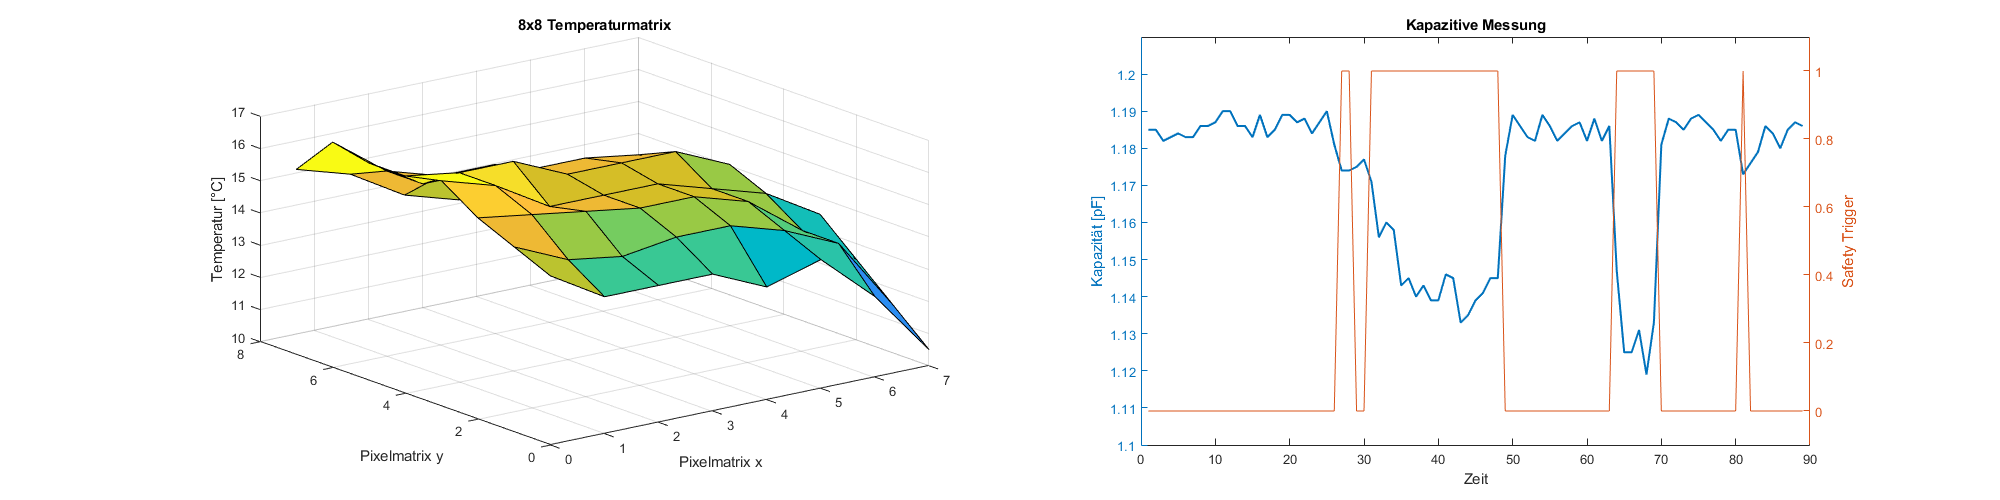

figure('position', [1 1 2000 500])
while(1)
    % get data and split values
    in = fscanf(s);
    in_split = split(in, ',');
    in_split(end) = [];
    
    %--------- temperature visualisation ---------
    % temperature-values in Z_dbl
    Z_dbl = str2double(in_split(2:end));
    
    % wait for 64 values
    length(Z_dbl);
    if length(Z_dbl) < 64
        continue;
    end
    Z = reshape(Z_dbl, [], 8);
    
    % plot data
    subplot(1,2,1), surf(X,Y,Z);
    title("8x8 Temperaturmatrix"); xlabel('Pixelmatrix x'); ylabel('Pixelmatrix y'); zlabel('Temperatur [°C]');
    %---------------------------------------------
    
    %--------- capacitive visualisation ---------
    % get the capacitive value
    data(i) = str2double(in_split(1));
    
    % safety trigger
    if numel(data) >= 10
        mean_Nominal = sum(data(1:10)) / 10;
        
        if data(i) <= mean_Nominal - 0.01
            safety(i) = 1;
        else
            safety(i) = 0;
        end
    end
    
    % plot data
    if i <= 400
        subplot(1,2,2)
        yyaxis left, plot(data,'Linewidth',1.5);
        title("Kapazitive Messung"); xlabel('Zeit'); ylabel('Kapazität [pF]'); ylim([1.1, 1.21]);
        yyaxis right, plot(safety);
        ylabel('Safety Trigger'); ylim([-0.1, 1.1]);
    else
        subplot(1,2,2)
        yyaxis left, plot(data(end-400:end),'Linewidth',1.5);
        title("Kapazitive Messung"); xlabel('Zeit'); ylabel('Kapazität [pF]'); ylim([1.1, 1.21]); ylim([1.1, 1.21]);
        yyaxis right, plot(safety(end-400:end));
        ylabel('Safety Trigger'); ylim([-0.1, 1.1]); ylim([-0.1, 1.1]);
    end
    %---------------------------------------------
    
    pause(0.01);
    % update counter for the capacitive flowing graph
    i = i+1;
end